% Parameters
alpha = 2; % Blackman window
window_length = 21;
cutoff_frequency = pi / (alpha + 1);

% Design FIR filters with different windows
rectangular_filter = fir1(window_length-1, cutoff_frequency/(pi), 'low', rectwin(window_length));
blackman_filter = fir1(window_length-1, cutoff_frequency/(pi), 'low', blackman(window_length));

% Impulse responses on the same graph using different colors
figure;
stem(rectangular_filter, 'b', 'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
hold on;
stem(blackman_filter, 'r', 'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
hold off;
title('Impulse Response of Low-Pass FIR Filters');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Rectangular Window', 'Blackman Window');
grid on;

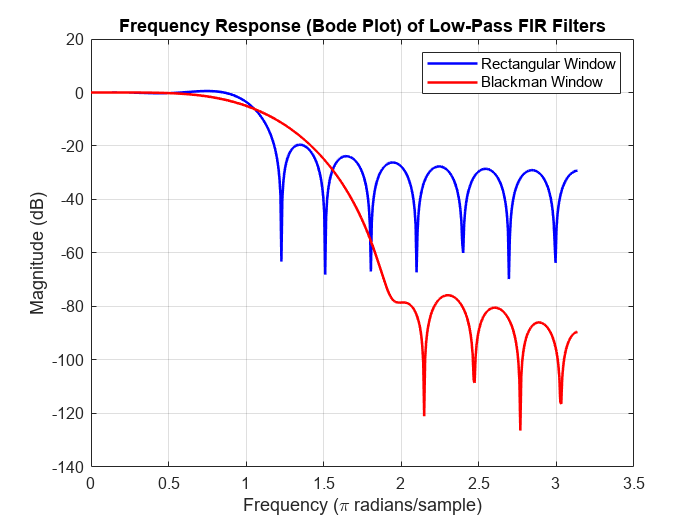


% Frequency responses on the same graph using different colors
[frequency_response_rect, freq_rect] = freqz(rectangular_filter, 1, 'half');
[frequency_response_blackman, freq_blackman] = freqz(blackman_filter, 1, 'half');

figure;
plot(freq_rect, 20*log10(abs(frequency_response_rect)), 'b', 'LineWidth', 1.5);
hold on;
plot(freq_blackman, 20*log10(abs(frequency_response_blackman)), 'r', 'LineWidth', 1.5);
hold off;
title('Frequency Response (Bode Plot) of Low-Pass FIR Filters');
xlabel('Frequency (\pi radians/sample)');
ylabel('Magnitude (dB)');
legend('Rectangular Window', 'Blackman Window');
grid on;


% Comment on the filters
disp('The rectangular window filter has a sharper transition band and higher stopband attenuation compared to the Blackman window filter.');

The rectangular window filter has a sharper transition band and higher stopband attenuation compared to the Blackman window filter.
